clear all;
close all;
sigmax=spinOp(5/2,'x');
sigmay=spinOp(5/2,'y');

initial_state=[1 0 0 0 0 0]';
filename="sigmax2+sigmax.gif";
precess_time_duration=[pi/2];
delay=0.03;
for i=1:length(precess_time_duration)
    precess_time=precess_time_duration(i);
    state=ham_evolve(sigmay^2+sigmay,initial_state,precess_time);
    [oneframe,fig]=frame(state);
    im=frame2im(oneframe);
    [imind,cm]=rgb2ind(im,256);
    if i==1
        imwrite(imind,cm,filename,"gif","LoopCount",inf,"DelayTime",delay);
    else
        imwrite(imind,cm,filename,"gif","WriteMode","append","DelayTime",delay);
    end
    disp(i/length(precess_time_duration))
end

     1



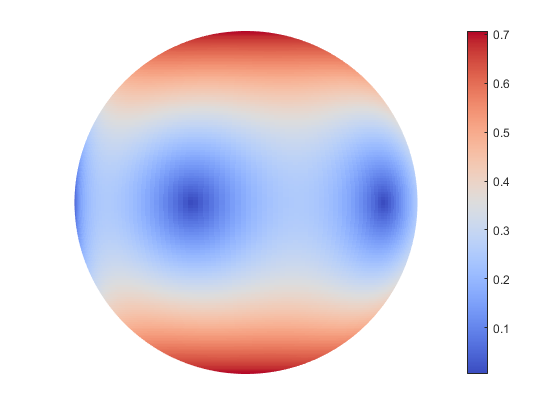


set(fig,'Visible',"on");

function [f1,f2]=frame(state)
m=200;n=200;J=5/2;
theta_list=[0:pi/(m-1):pi];
phi_list=[0:2*pi/(n-1):2*pi];
for i=1:length(theta_list)
    for j=1:length(phi_list)
        phi=phi_list(j);
        theta=theta_list(i);
        wigner_result(i,j)=abs(spin_coherent(theta,phi)'*state);
    end
end
f1=wigner_plot_only_fun(wigner_result);
f2=f1;
f1=getframe(f1);
end
function f1=wigner_plot_only_fun(wigner_result)
    [m,n]=size(wigner_result);
    theta_list=[0:pi/(m-1):pi];
    phi_list=[0:2*pi/(n-1):2*pi];
   
    f1=figure;
    theta_list=pi/2-theta_list;
    [theta2,phi2]=meshgrid(theta_list,phi_list);
    [x,y,z]=sph2cart(phi2,theta2,1);
    surf=mesh(x,y,z,real(wigner_result'));
    xlim([-1 1]);
    zlim([-1 1]);
    ylim([-1 1]);

    %caxis([-1 1.0]);
    xlabel('x');
    ylabel('y');
    %view([0 90])
    set(f1,"Visible","Off");
    daspect([1 1 1]);
    %axis equal;
    set(surf,"LineStyle","none", "FaceColor","texturemap",...
        "FaceLighting","gouraud");
    colorbar('off');
    box off;
    axis off;
    colormap('jet');
    cw=mymap('coolwarm');
    %cw=mymap('bwr');
    colormap(cw);
    view([0 0]);
    colorbar;
    %cMap=getPyPlot_cMap('coolwarm');
    %colormap(cMap);
end

function state=spin_coherent(theta,phi)
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');
polar=[1 0 0 0 0 0]';
state1=ham_evolve(sigmay,polar,theta);
state=ham_evolve(sigmaz,state1,phi);
end

function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end